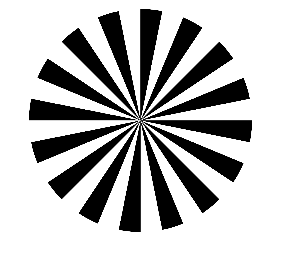

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
dx = 20*mm/Nx; 
dy = dx;

% Longitud de Onda de iluminación
lambda = 533*nm;

% Apertura númerica
AN = 0.25;

estrella = imread('Siemens.png');
estrella = imresize(estrella,Nx/1200);
imshow(estrella)

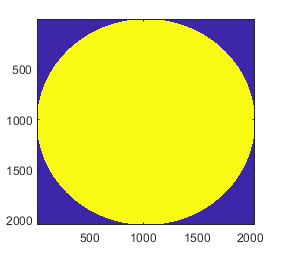


%La imagen pasará por un primer lente, el cual es un 
% objetivo 4x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f1 = 50*mm;
f2 = 200*mm;

Diam = f1*2*AN;

% Pupila
radioAberturaCirc = 10*mm/dx;
aberturaCircular = filtroCircular ([Nx/2 Ny/2],radioAberturaCirc,[Ny Nx]);
imagesc(aberturaCircular)

fourierEstrella = fft2(estrella);
planoPupila = (fft2(fourierEstrella));
propagacion = (abs(planoPupila));

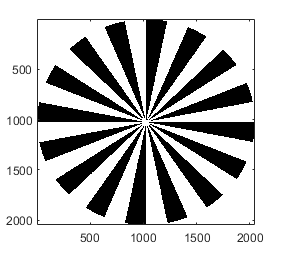

imagesc(propagacion)

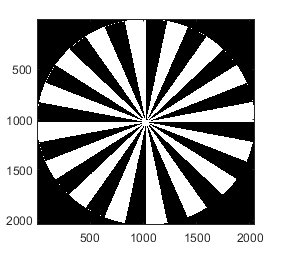

%Paso por la pupila
nueva = propagacion.*aberturaCircular;
imagesc(nueva)

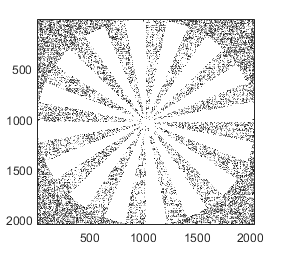

%Paso por la segunda lente 
fouriernueva = fft2(nueva);
planoFinal = fft2(fouriernueva);
propagacionFinal = (abs(planoFinal));
imagesc(propagacionFinal)